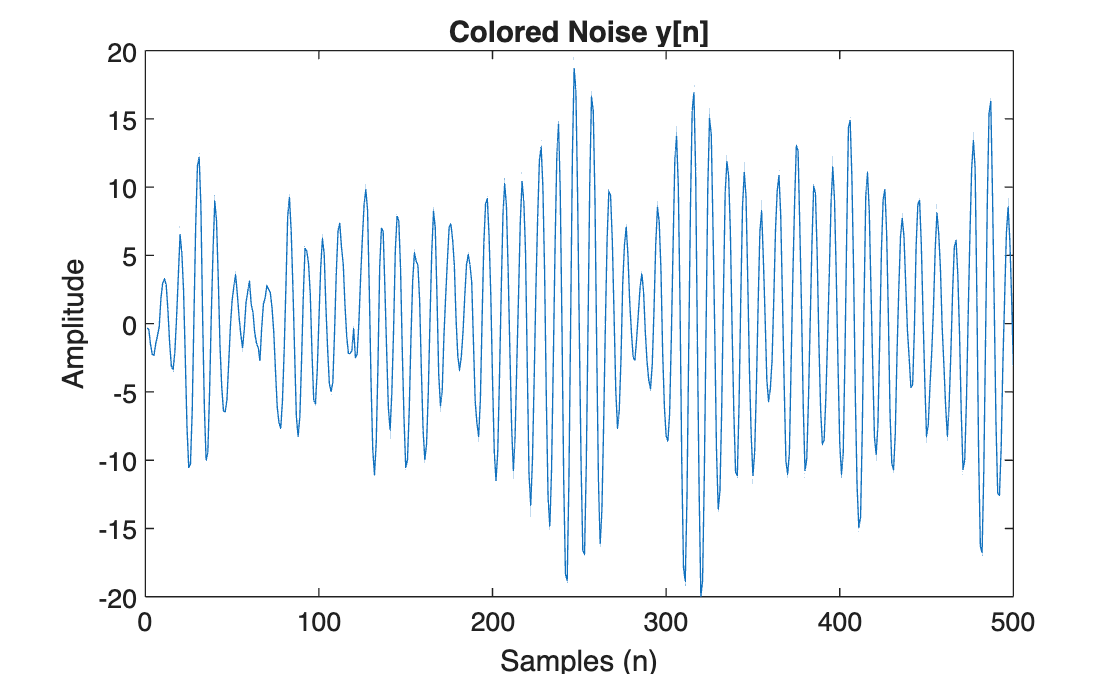

clc
close all;
clear;

% Rocio Lopez

fs = 10000;
N = 500;
w = linspace(0, pi, 1024);
x = randn(1,N);

a = [1, -1.585, 0.96];
y = filter(1,a,x);
figure;
plot(y);
xlabel('Samples (n)')
ylabel('Amplitude')
title('Colored Noise y[n]')

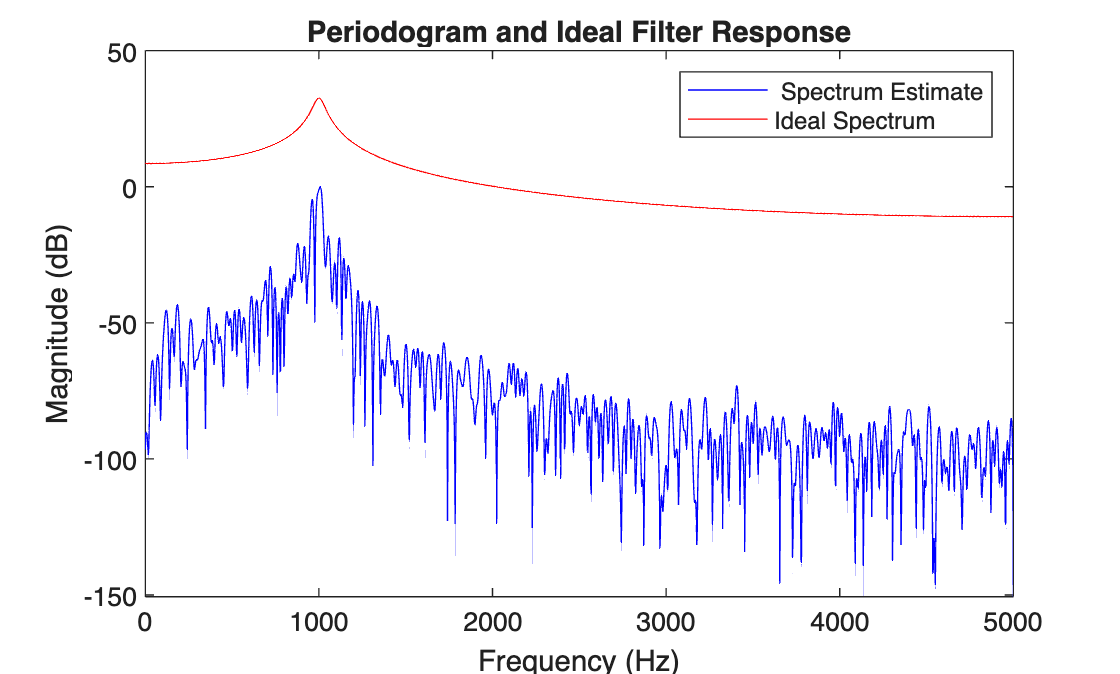



[H, fH] = freqz(1, a, 2^12, fs); 
H_mag = abs(H).^2;


[Y, fY] = periodogram(y, [], 2^12, fs);
Y_ave = mean(Y);


figure;
plot(fY, 20*log10(Y), 'b'); 
hold on;
plot(fH, 10*log10(H_mag), 'r');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Periodogram and Ideal Filter Response');
legend(' Spectrum Estimate', 'Ideal Spectrum');
hold off;

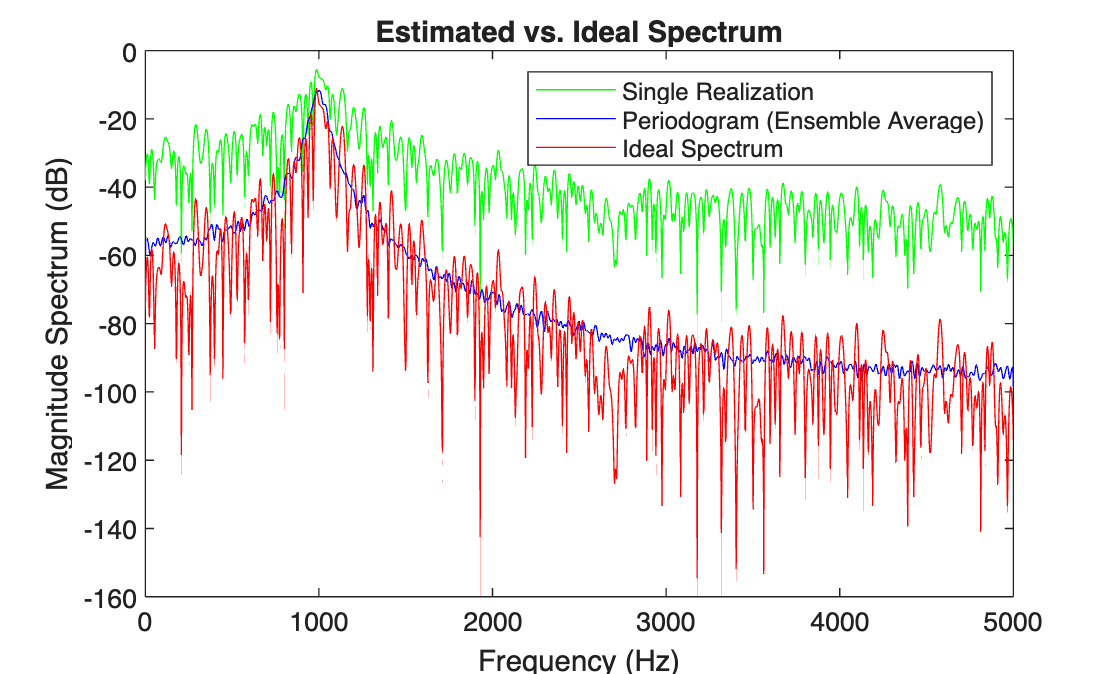



Y = zeros(50, 2049); 

for k = 1:50
    x = randn(1, N);          
    y = filter(1, a, x);      
    [Y(k, :), fY] = periodogram(y, [], 2^12, fs);         
end

Y_ave=mean(Y);
single_realization = Y(1, :);

bias = Y_ave - H_mag;
Y_var = var(Y);

figure;
plot(fY, 10*log10(single_realization),'g');
hold on;
plot(fY, 20*log10(Y_ave), 'b'); 
plot(fY, 10*log10(abs(single_realization).^2), 'r'); 
xlabel('Frequency (Hz)');
ylabel('Magnitude Spectrum (dB)');
legend('Single Realization','Periodogram (Ensemble Average)', 'Ideal Spectrum');
title('Estimated vs. Ideal Spectrum');
hold off;

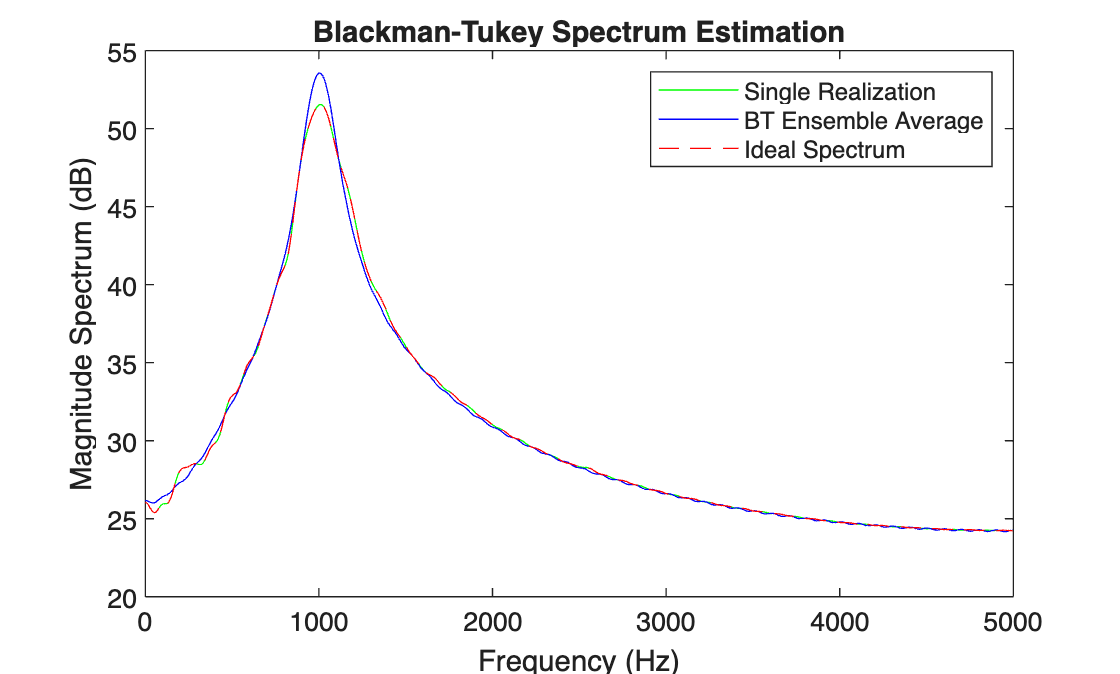


Nf=2^11; 
f=0:fs/Nf:(Nf-1)/Nf*fs/2; 
M = round(N/5 +1);
wind = hamming(2*M-1);
Y_bt = zeros(50, 1024);  

for k=1:50
    x = randn(1, N);
    y(k,:) = filter(1, a, x);
    [Y_bt(k,:),~]=per_smooth(y(k,:),wind,M);
end

Y_bt_ave = mean(Y_bt);
Y_bt_single = Y_bt(1, :);

figure;
plot(f, 20*log10(Y_bt_single), 'g'); 
hold on;
plot(f, 20*log10(Y_bt_ave), 'b');
plot(f, 10*log10(abs(Y_bt_single).^2), 'r--'); 
xlabel('Frequency (Hz)');
ylabel('Magnitude Spectrum (dB)');
legend('Single Realization', 'BT Ensemble Average', 'Ideal Spectrum');
title('Blackman-Tukey Spectrum Estimation');
hold off;

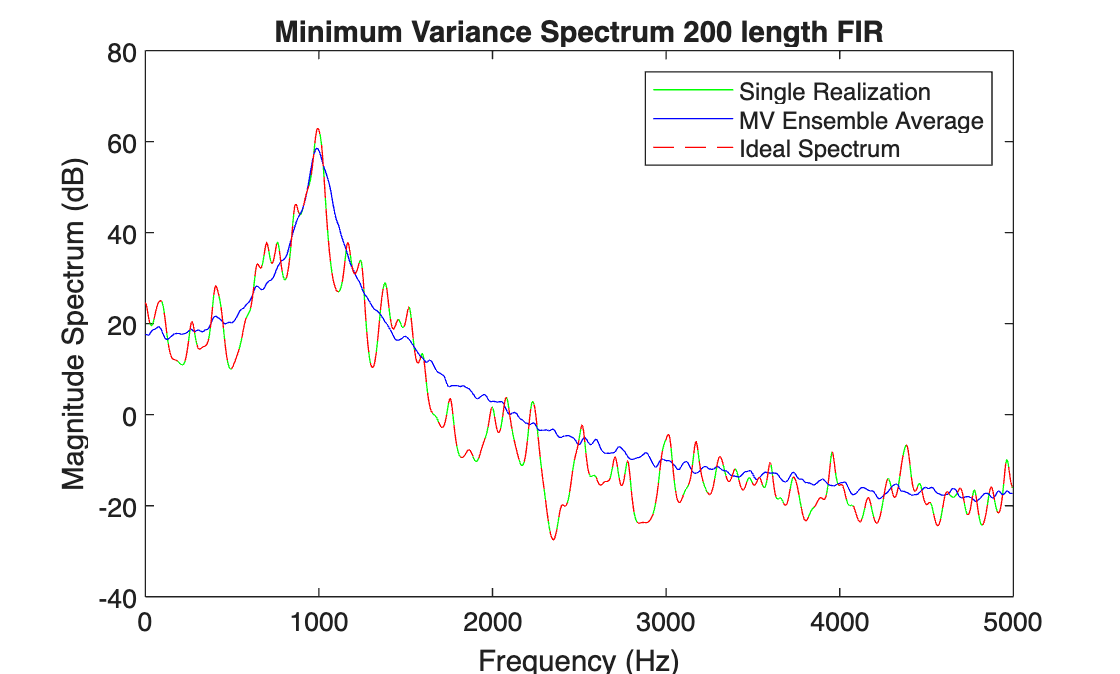



p = 200;
Y_MV = zeros(50, 1024);

for k = 1:50
    x = randn(1, N);
    y = filter(1, a, x);
    [Py_MV, ~] = MV(y, p, w);
    Y_MV(k, :) = Py_MV;
end
Y_MV_ave = mean(Y_MV);
Y_MV_single = Y_MV(1, :);

figure;
plot(f, 20*log10(Y_MV_single), 'g'); 
hold on;
plot(f, 20*log10(Y_MV_ave), 'b');
plot(f, 10*log10(abs(Y_MV_single).^2), 'r--');
xlabel('Frequency (Hz)');
ylabel('Magnitude Spectrum (dB)');
legend('Single Realization', 'MV Ensemble Average', 'Ideal Spectrum');
title('Minimum Variance Spectrum 200 length FIR');
hold off;

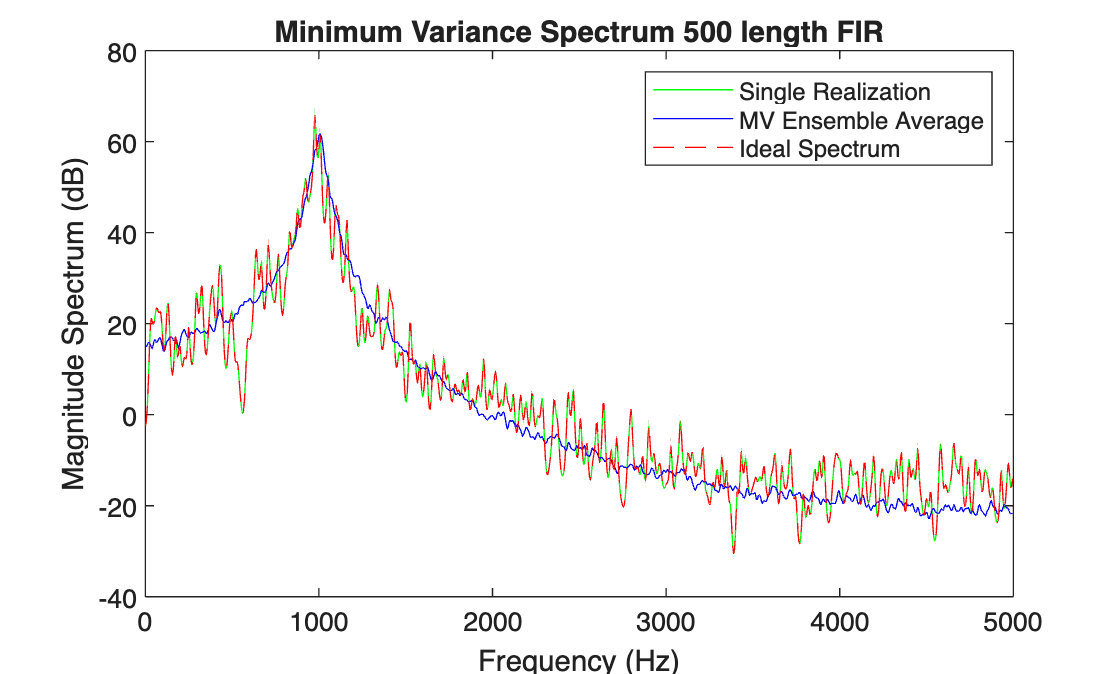



p6 = 500;
Y_MV = zeros(50, 1024);

for k = 1:50
    x = randn(1, N);
    y = filter(1, a, x);
    [Py_MV5, ~] = MV(y, p6, w);
    Y_MV5(k, :) = Py_MV5;
end
Y_MV5_ave = mean(Y_MV5);
Y_MV5_single = Y_MV5(1, :);

figure;
plot(f, 20*log10(Y_MV5_single), 'g'); 
hold on;
plot(f, 20*log10(Y_MV5_ave), 'b');
plot(f, 10*log10(abs(Y_MV5_single).^2), 'r--');
xlabel('Frequency (Hz)');
ylabel('Magnitude Spectrum (dB)');
legend('Single Realization', 'MV Ensemble Average', 'Ideal Spectrum');
title('Minimum Variance Spectrum 500 length FIR');
hold off;

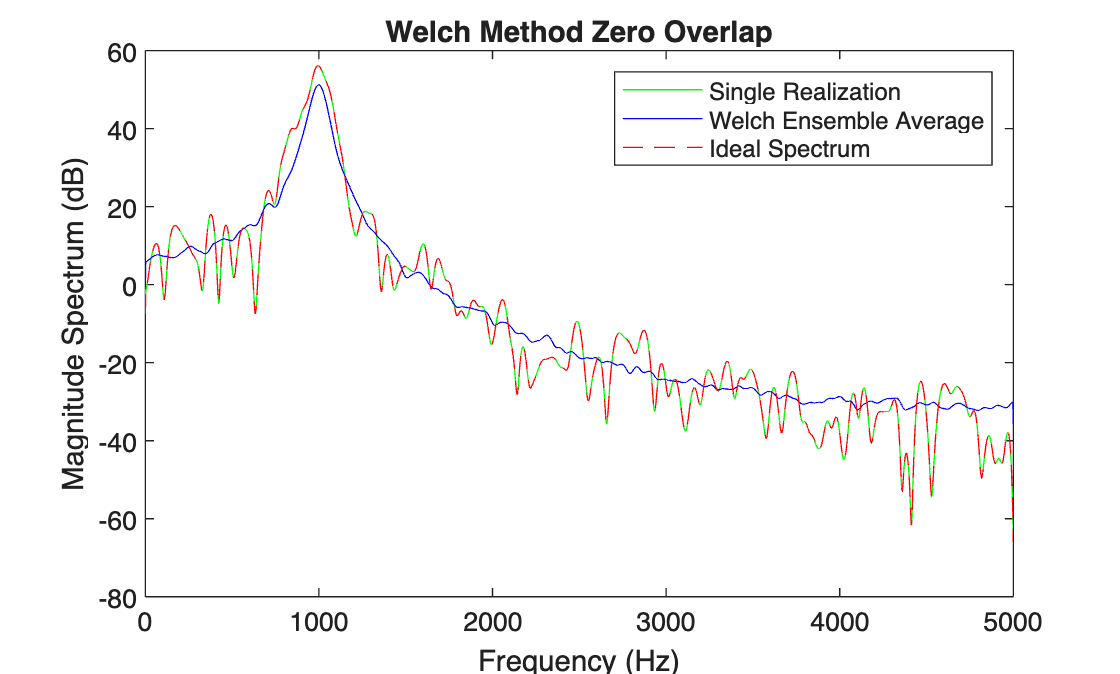




K=3;
L=2*N/(K+1);
wind = hamming(L);
Y_welch = zeros(50, 2049);  

for k=1:50
    x = randn(1, N);
    y(k,:) = filter(1, a, x);
    [Y_welch(k,:),~]=pwelch(y(k,:),wind,0,2^12);
end
Y_welch_ave = mean(Y_welch);
Y_welch_single = Y_welch(1, :);

figure;
plot(fY, 20*log10(Y_welch_single), 'g'); 
hold on;
plot(fY, 20*log10(Y_welch_ave), 'b');
plot(fY, 10*log10(abs(Y_welch_single).^2), 'r--');
xlabel('Frequency (Hz)');
ylabel('Magnitude Spectrum (dB)');
legend('Single Realization', 'Welch Ensemble Average', 'Ideal Spectrum');
title('Welch Method Zero Overlap');
hold off;

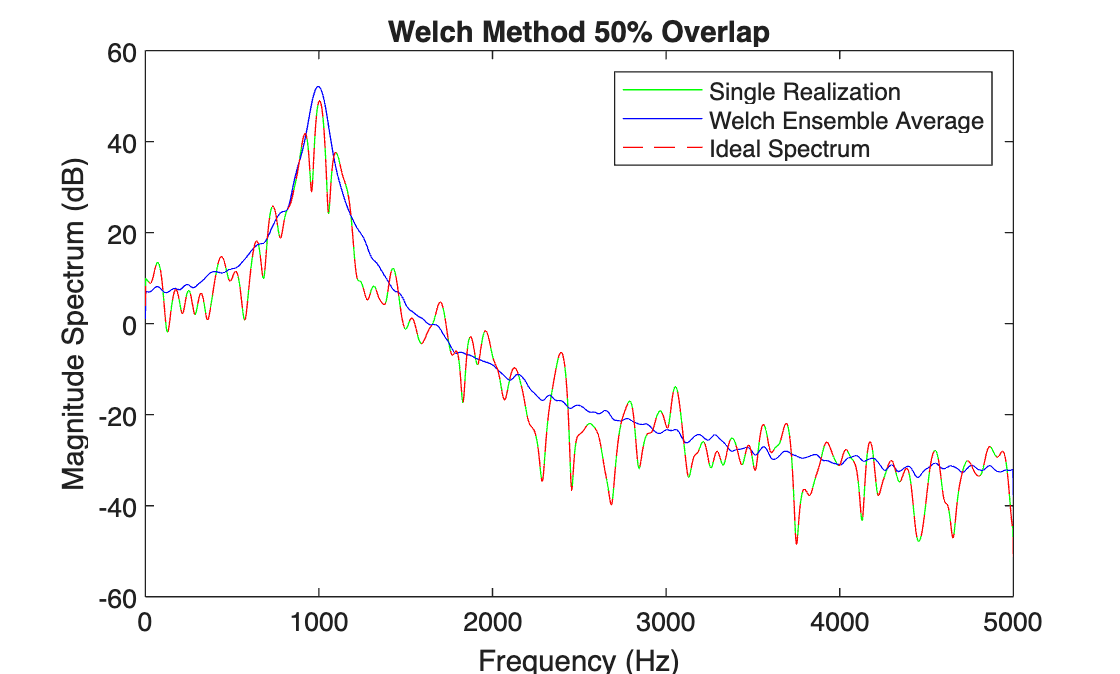



for k=1:50
    x = randn(1, N);
    y(k,:) = filter(1, a, x);
    [Y_welch50(k,:),~]=pwelch(y(k,:),wind,L/2,2^12);
end
Y_welch50_ave = mean(Y_welch50);
Y_welch50_single = Y_welch50(1, :);

figure;
plot(fY, 20*log10(Y_welch50_single), 'g'); 
hold on;
plot(fY, 20*log10(Y_welch50_ave), 'b');
plot(fY, 10*log10(abs(Y_welch50_single).^2), 'r--');
xlabel('Frequency (Hz)');
ylabel('Magnitude Spectrum (dB)');
legend('Single Realization', 'Welch Ensemble Average', 'Ideal Spectrum');
title('Welch Method 50% Overlap');
hold off;

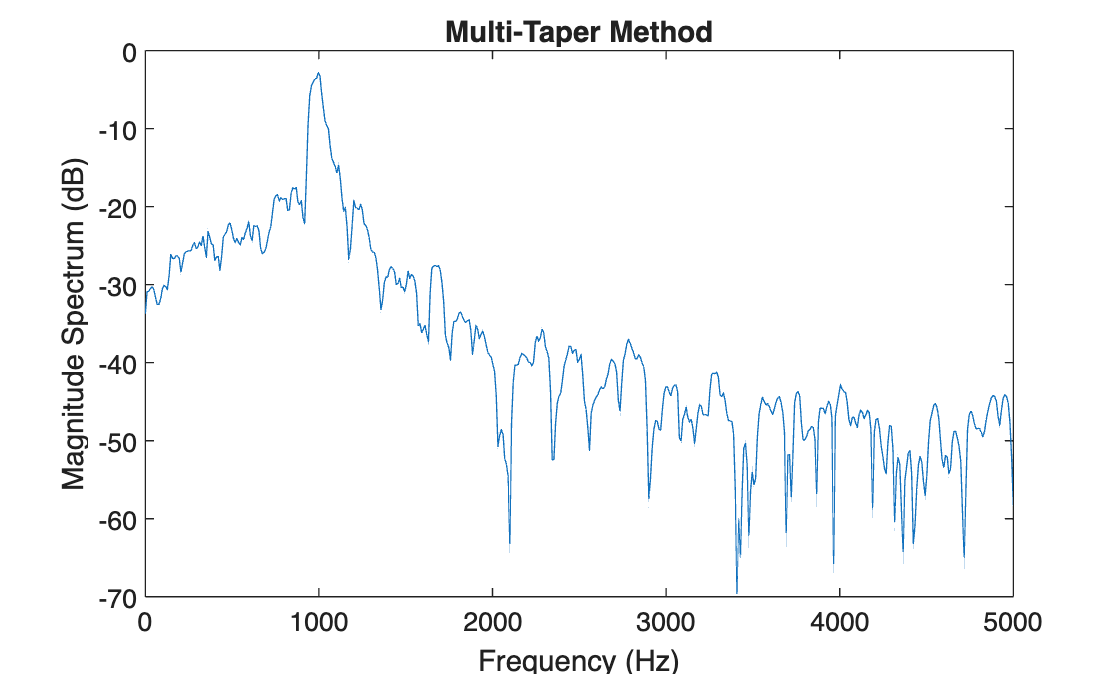



[Ymt, fmt] = pmtm(y(k,:), 2, 1024, fs);
Ymt_ave = mean(Ymt);
Ymt_single = Ymt(1,:);
Y_dB=10*log10(Ymt);
figure;
plot(fmt,Y_dB);
xlabel('Frequency (Hz)');
ylabel('Magnitude Spectrum (dB)');
title('Multi-Taper Method');


 
function [Px,w] = per_smooth(y,wind,M) 



x=y(:);
r = xcorr(x, M - 1, 'biased');
r = r(M:end) .* wind(M:end); 
[Pxx,w]=freqz(r,1, 1024);
Px=abs(Pxx);

end

function [Px,R] = MV(x,p,w) 


N=2*length(w);
x=x(:);
r=1/p*xcorr(x(1:p),x(1:p));
M=length(r);
R=toeplitz(r((M+1)/2:end));
[V,D]=eig(R);
d=1./(abs(diag(D))+eps);
W=abs(fft(V,N)).^2;
Px1=fftshift((1+p)./(W*d));
Px=Px1(N/2+1:end)';

end